# **PID Controller Tuner Using Step Response Plot**

## Set PID Values

Kp=2.5;
Ki=1.3;
Kd=0.4;


## Set Gear Ratio

N = 20;

## Set Simulation Parameters

config.maxStep = '0.001';
config.stepTime = 0;
config.torqueStart = 0;
config.torqueEnd = 0;
config.Td = 0;
config.stopTime = "5";
config.stepSize = 1;

#### Get Hardware Values

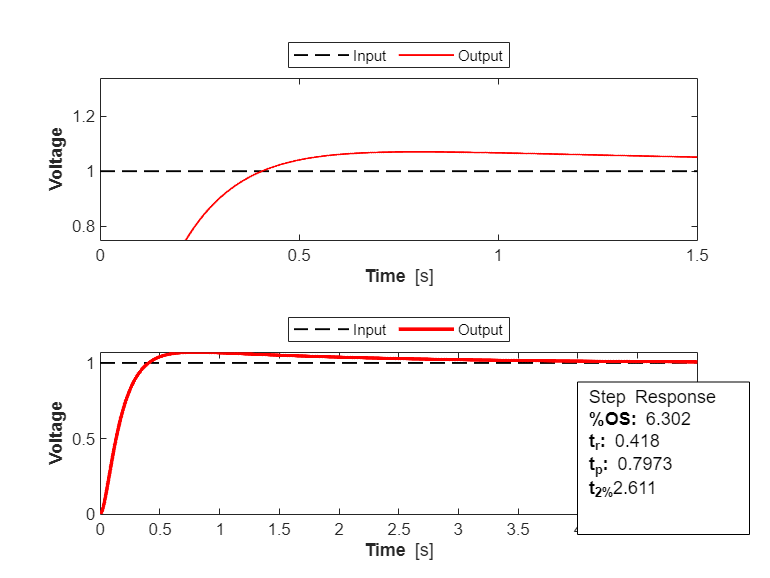

% H = getHardwareValues(Kp,Ki,Kd);
% if(numel(H.R1)~= 0)
%     R1_ = [H.R1(1) H.R1(2)];
%     fprintf('\bR1 = %0.5g %0.5g\n',R1_(1),R1_(2));
%     R2_ = [H.R2(1) H.R2(2)];
%     fprintf('\bR2 = %0.5g %0.5g\n',R2_(1),R2_(2));
%     C1_ = [H.C1(1) H.C1(2)];
%     fprintf('\bC1 = %0.5g %0.5g\n',C1_(1),C1_(2));
%     C2_ = [H.C2(1) H.C2(2)];
%     fprintf('\bC2 = %0.5g %0.5g\n',C2_(1),C2_(2));
% else
%     disp("Impossible with Available Hardware")
% end
pid_step;

 
step_tuner_plot;